## **SIO 207A HW-5**

**Ruipu Ji**

A typical sampling rate for underwater acoustic signal processing systems is $f_s =1\;\textrm{kHz}$. Assume that a special purpose hardware FFT is available where NFFT = 256. Using the FFT hardware, it is desired to resolve two sinusoids which are located at $f_1 =37\ldotp 5\;\textrm{Hz}$ and $f_2 =40\ldotp 5\;\textrm{Hz}$. 

#### I. Preliminary Calculations

*Define the frequency parameters and the discrete time signal:*

% Define the frequency parameters.
fs = 1000; % Sampling frequency (Hz).
f1 = 37.5; % Frequency of signal 1.
f2 = 40.5; % Frequency of signal 2.

**A. What is the FFT bin width in terms of analog frequency?**

% Calculate the FFT bin width in terms of analog frequency.
NFFT = 256;
BinWidth = fs/NFFT;

% Display the result.
fprintf('FFT bin width in terms of analog frequency = %f Hz', BinWidth);

FFT bin width in terms of analog frequency = 3.906250 Hz

**B. In which bin (i.e. frequency index **$k=\left\lbrace 0,1\cdots N-1\right\rbrace$** does **$f_1$** reside? In which bin does **$f_2$** reside?**

% Calculate the frequency index for analog frequencies.
k1_prime = round(f1/BinWidth);
k2_prime = round(f2/BinWidth);

% Display the result.
fprintf('Frequency bin index for f1 = %d', k1_prime);

Frequency bin index for f1 = 10

fprintf('Frequency bin index for f2 = %d', k2_prime);

Frequency bin index for f2 = 10

**C. Will the two sinusoids be resolvable given that a rectangular window is used with the FFT? Speculate on whether or not any other type of window would be beneficial.**

Given $f_s =1\;\textrm{kHz}$ and NFFT = 256, the frequency bin index for $f_1$ and $f_2$ are both 10. This frequency index does not depend on the window applied to the signal. Therefore, the two sinusoids are not resolvable given a rectangular window or any other window with the 256-point FFT.

#### II. Decimation

Decimation of the time series by a factor of 8 is proposed in order to achieve higher resolution. A low pass filter must be designed and implemented. The output sequence will be decimated to achieve an effective sampling rate of $f_s \prime =\frac{f_s }{8}=125\;\textrm{Hz}$.Repeat Part I A - C.

**A. What is the FFT bin width in terms of analog frequency?**

% Define the effective sampling rate after decimation.
fs_prime = fs/8;

% Calculate the FFT bin width in terms of analog frequency.
NFFT = 256;
BinWidth_prime = fs_prime/NFFT;

% Display the result.
fprintf('FFT bin width in terms of analog frequency = %f Hz', BinWidth_prime);

FFT bin width in terms of analog frequency = 0.488281 Hz

**B. In which bin (i.e. frequency index **$k=\left\lbrace 0,1\cdots N-1\right\rbrace$** does **$f_1$** reside? In which bin does **$f_2$** reside?**

% Calculate the frequency index for analog frequencies.
k1_prime = round(f1/BinWidth_prime);
k2_prime = round(f2/BinWidth_prime);

% Display the result.
fprintf('Frequency bin index for f1 = %d', k1_prime);

Frequency bin index for f1 = 77

fprintf('Frequency bin index for f2 = %d', k2_prime);

Frequency bin index for f2 = 83

**C. Will the two sinusoids be resolvable given that a rectangular window is used with the FFT? Speculate on whether or not any other type of window would be beneficial.**

Given $f_s \prime =\frac{f_s }{8}=125\;\textrm{Hz}$ and NFFT = 256, the frequency bin index for $f_1$ is 77, and the frequency index for $f_2$ is 83. This frequency index does not depend on the window applied to the signal. Therefore, the two sinusoids are resolvable given a rectangular window or any other window with the 256-point FFT.

#### III. FIR Low Pass Filter Critical Frequencies

A 64-coefficient, linear phase, FIR low pass filter is to be designed for the decimator. An analog cutoff frequency $f_c =50\;\mathrm{Hz}$ is desired and defines the ideal passband edge. The filter stopband is defined by $\frac{f_s \prime }{2}=62\ldotp 5\textrm{Hz}$. Compare the transition width specified and the bin width of a 64-point FFT. Speculate on how good this filter is likely to be.

*Design the FIR low pass filter:*

N = 64; % Number of coefficients.
fc = 50; % Cutoff frequency.
f_stopband = fs_prime/2; % Stopband frequency.

% Design the FIR low pass filter.
frequency = [0 fc/(fs/2) f_stopband/(fs/2) 1];
amplitude = [1 1 0 0];
LPF = firpm(N-1, frequency, amplitude);

*Plot the impulse response h(n) and frequency response |H(f)| :*

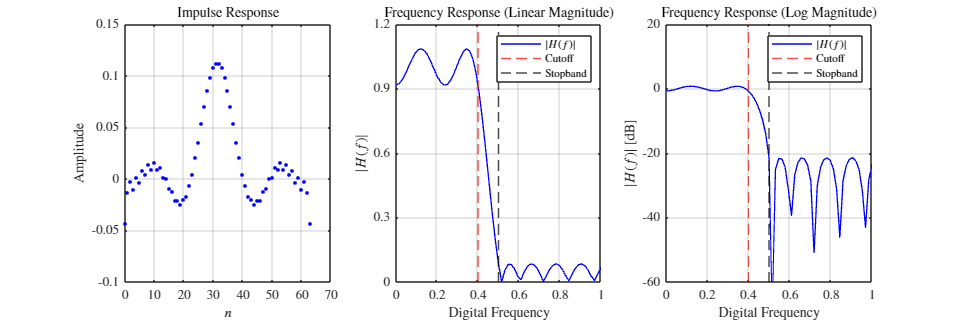

% Default plot settings.
set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

% Calcualte the frequency response.
[H,F] = freqz(LPF, 1, NFFT, fs);

% Plot the results.
figure('Position',[0 0 1200 400]);

subplot(1,3,1); % Plot the impulse response (filter coefficients).
scatter(0:N-1, LPF, 8, 'b', 'o', 'filled');
grid on;
box on;
xlim([0 70]);
xticks(0:10:70);
ylim([-0.1 0.15]);
yticks(-0.1:0.05:0.15);
xlabel('$n$');
ylabel('Amplitude');
title('Impulse Response');

subplot(1,3,2); % Plot the frequency response (linear magnitude).
hold on;
plot(F/fs_prime, abs(H), 'b', 'LineWidth', 1);
xline(fc/fs_prime, 'r--', 'LineWidth', 1);
xline(f_stopband/fs_prime, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 1]);
xticks(0:0.2:1);
ylim([0 1.2]);
yticks(0:0.3:1.2);
xlabel('Digital Frequency');
ylabel('$|H(f)|$');
legend('$|H(f)|$', 'Cutoff', 'Stopband');
title('Frequency Response (Linear Magnitude)');

subplot(1,3,3); % Plot the frequency response (log magnitude).
plot(F/fs_prime, 20*log10(abs(H)), 'b', 'LineWidth', 1);
xline(fc/fs_prime, 'r--', 'LineWidth', 1);
xline(f_stopband/fs_prime, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 1]);
xticks(0:0.2:1);
ylim([-60 20]);
yticks(-60:20:20);
xlabel('Digital Frequency');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff', 'Stopband');
title('Frequency Response (Log Magnitude)');

Figure 1. Impulse response and frequency response of the FIR low pass filter.

*Compare the transition width and the bin width of a 64-point FFT:*

% Calculate the transition width and the bin width of a 64-point FFT.
TransitionWidth = f_stopband - fc;
BinWidth = fs/N;

% Display the result.
fprintf('Transition width = %f Hz', TransitionWidth);

Transition width = 12.500000 Hz

fprintf('Bin width of a 64-point FFT = %f Hz', BinWidth);

Bin width of a 64-point FFT = 15.625000 Hz

#### IV. Equiripple Filter Design

**A. Using an equiripple filter design algorithm, design the required decimation filter. **

Consider three cases: (1) passband / stopband weighting ratio = 10 (i.e. minimizing errors in the passband is 10 times more important than minimizing errors in the stopband), (2) passband / stopband weighting ratio = 1, and (3) passband / stopband weighting ratio = 1/10.

*Filter design and frequency response calculation:*

N = 64; % Number of coefficients.
fc = 50; % Cutoff frequency.
f_stopband = fs_prime/2; % Stopband frequency.

Weights = [1 10; 1 1; 10 1]; % Define weight ratios.

frequency = [0 fc/(fs/2) f_stopband/(fs/2) 1];
amplitude = [1 1 0 0];

% Initialization for arrays to store the results.
h = []; % Impulse response coefficients (filter coefficients).
H = []; % Frequency response.
F = []; % Frequency.

% Loop over each weight ratio:
for i = 1:size(Weights,1)
    h(:,i) = firpm(N-1, frequency, amplitude, Weights(i,:)); % Filter design.
    [H(:,i),F(:,i)] = freqz(h(:,i), 1, 1024, fs); % Calculate frequency response.
end

*Plot the impulse response h(n) and frequency response |H(f)| :*

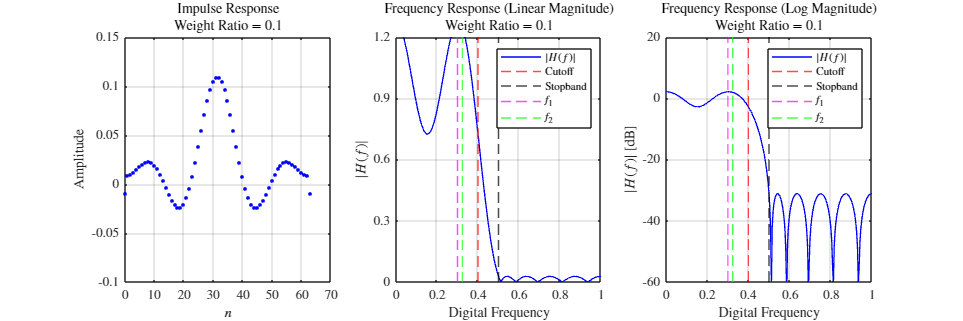

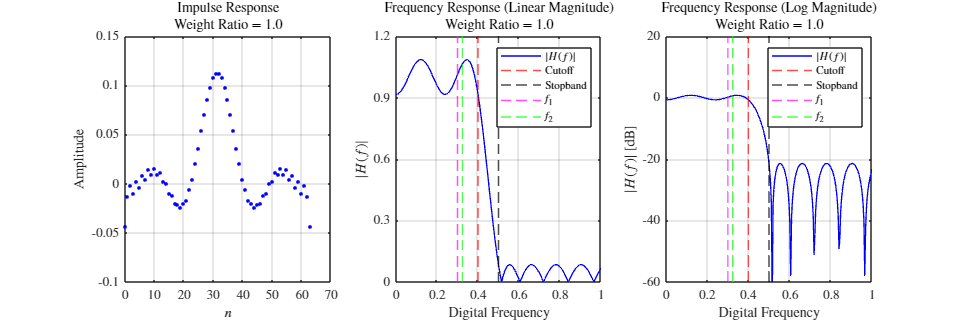

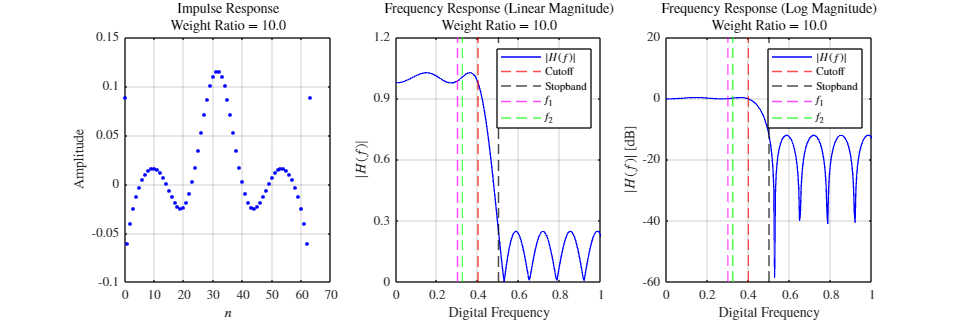

% Plot the results.
for i = 1:size(Weights,1)
    figure('Position',[0 0 1200 400]);

    subplot(1,3,1); % Plot the impulse response (filter coefficients).
    scatter(0:N-1, h(:,i), 8, 'b', 'o', 'filled');
    grid on;
    box on;
    xlim([0 70]);
    xticks(0:10:70);
    ylim([-0.1 0.15]);
    yticks(-0.1:0.05:0.15);
    xlabel('$n$');
    ylabel('Amplitude');
    title(sprintf('Impulse Response\nWeight Ratio = %.1f', Weights(i,1)/Weights(i,2)));
    
    subplot(1,3,2); % Plot the frequency response (linear magnitude).
    hold on;
    plot(F(:,i)/fs_prime, abs(H(:,i)), 'b', 'LineWidth', 1);
    xline(fc/fs_prime, 'r--', 'LineWidth', 1);
    xline(f_stopband/fs_prime, 'k--', 'LineWidth', 1);
    xline(f1/fs_prime, 'm--', 'LineWidth', 1);
    xline(f2/fs_prime, 'g--', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 1]);
    xticks(0:0.2:1);
    ylim([0 1.2]);
    yticks(0:0.3:1.2);
    xlabel('Digital Frequency');
    ylabel('$|H(f)|$');
    legend('$|H(f)|$', 'Cutoff', 'Stopband', '$f_1$', '$f_2$');
    title(sprintf('Frequency Response (Linear Magnitude)\nWeight Ratio = %.1f', Weights(i,1)/Weights(i,2)));
    
    subplot(1,3,3); % Plot the frequency response (log magnitude).
    plot(F(:,i)/fs_prime, 20*log10(abs(H(:,i))), 'b', 'LineWidth', 1);
    xline(fc/fs_prime, 'r--', 'LineWidth', 1);
    xline(f_stopband/fs_prime, 'k--', 'LineWidth', 1);
    xline(f1/fs_prime, 'm--', 'LineWidth', 1);
    xline(f2/fs_prime, 'g--', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 1]);
    xticks(0:0.2:1);
    ylim([-60 20]);
    yticks(-60:20:20);
    xlabel('Digital Frequency');
    ylabel('$|H(f)|$ [dB]');
    legend('$|H(f)|$', 'Cutoff', 'Stopband', '$f_1$', '$f_2$');
    title(sprintf('Frequency Response (Log Magnitude)\nWeight Ratio = %.1f', Weights(i,1)/Weights(i,2)));                                   
end

Figure 2. Impulse response and frequency response for the FIR low pass filter with different weight ratios.

It is observed that the passband ripples decreases and the stopband ripples increases as the weight ratio increases. The frequency response in the passband become smoother with a larger weight ratio.

#### V. Filter Implementation

Implement the FIR filter with passband / stopband weighting ratio = 1 and use it to filter a time series obtained from sampling the sum of two equal amplitude sinusoids at frequencies $f_2 =40\ldotp 5\;\mathrm{Hz}$ and $f_3 =100\;\mathrm{Hz}$. Using a good window function, compute the 256–point FFT of both the input and output time series. Plot these two spectra (dB) and comment on the sinusoid levels.

In this homework, an example signal $x\left(t\right)=\sin \left(2\pi f_2 t\right)+\sin \left(2\pi f_3 t\right)$ where $0\le t<1$ and the amplitudes of both sinusoids are equal to 1, is selected to be sampled and analyzed.

*Define the signal:*

% Define the frequency parameters.
fs = 1000; % Sampling frequency (Hz).
f2 = 40.5;
f3 = 100;

% Define the signal x(t).
t = (0:1/fs:(fs-1)/fs)'; % Time vector.
x = sin(2*pi*f2*t) + sin(2*pi*f3*t);

*Filter the signal:*

y = filtfilt(LPF, 1, x);

*Apply the Kaiser-Bessel window (α = 2.5 or β = πα = 7.85) and calculate the 256-point FFT:*

NFFT = 256;
KaiserBesselWindow = kaiser(NFFT, 7.85); % Kaiser-Bessel window (alpha = 2.5 or beta = alpha*pi = 7.85).

% Window the input and output signal.
x_windowed = x(1:NFFT).*KaiserBesselWindow;
y_windowed = y(1:NFFT).*KaiserBesselWindow;

% Calculate the 256-point FFT.
X = fft(x_windowed, NFFT); 
Y = fft(y_windowed, NFFT);

% Calculate the amplitude in log magnitude.
X_dB = 20*log10(abs(X));
Y_dB = 20*log10(abs(Y));

% Normalize the amplitude.
X_dB = X_dB - max(X_dB);
Y_dB = Y_dB - max(Y_dB);

*Plot the spectra:*

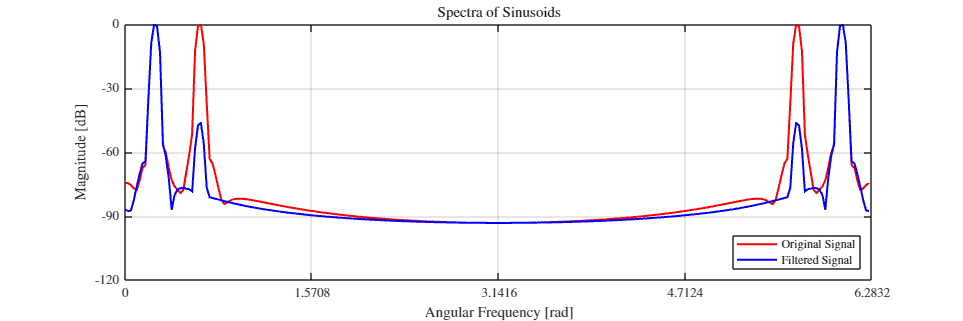

% Define the frequency vector.
f = (0:1/NFFT:(NFFT-1)/NFFT)*2*pi;

% Plot the result.
figure('Position',[0 0 1200 400]);
hold on;
plot(f, X_dB, 'r', 'LineWidth', 1.5);
plot(f, Y_dB, 'b', 'LineWidth', 1.5);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-120 0]);
yticks(-120:30:0);
xlabel('Angular Frequency [rad]');
ylabel('Magnitude [dB]');
legend('Original Signal', 'Filtered Signal', 'Location', 'southeast');
title('Spectra of Sinusoids');

Figure 3. Spectra of the original and filtered sinusoids.

Two peaks with the same magnitude are observed in the spectra of the original signal, which represent the two frequency components (40.5 Hz and 100 Hz) in the original signal. There are still two peaks in the spectra of the filtered signal, but the peak corresponding to the 100 Hz frequency component is reduced by the filter since 100 Hz stays in the stopband range. There are still some unfiltered parts for the 100 Hz component, which means there is some leakage for this filter.